import casadi.*

disp('--- AI-VEZÉRELT CASADI TUBE MPC INDÍTÁSA ---');

--- AI-VEZÉRELT CASADI TUBE MPC INDÍTÁSA ---



% Ellenőrzés: Megvan-e a betanított háló?
if ~exist('net', 'var')
    error('Hiba: Nem találom a "net" változót! Előbb futtasd le a tanító kódot.');
end

% 1. Pálya adatok (Referencia) - 1 kört futtatunk a teszthez
Ts = 0.1; 
V_target = 5; 
N = 15; 

ds = sqrt(diff(smooth_path(:,1)).^2 + diff(smooth_path(:,2)).^2);
dist = [0; cumsum(ds)];
t_path = dist / V_target; 
t_sim = 0:Ts:t_path(end); 

X_ref = interp1(t_path, smooth_path(:,1), t_sim, 'linear', 'extrap');
Y_ref = interp1(t_path, smooth_path(:,2), t_sim, 'linear', 'extrap');
RefMatrix = [X_ref', Y_ref', [diff(X_ref)/Ts, 0]', [diff(Y_ref)/Ts, 0]'];

% 2. Modell mátrixok (Kettős integrátor)
A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1];
B = [0 0; 0 0; Ts 0; 0 Ts];
K_lqr = dlqr(A, B, diag([10, 10, 1, 1]), diag([0.5, 0.5]));

% ==========================================
% 3. CASADI OPTIMIZÁCIÓ (AI JÓSLATTAL KIEGÉSZÍTVE)
% ==========================================
opti = casadi.Opti();

X = opti.variable(4, N+1); 
U = opti.variable(2, N);   

x0_param = opti.parameter(4, 1);         
ref_param = opti.parameter(4, N+1);      

% ---> ÚJ: Ez a paraméter fogadja a Neurális Háló jóslatát
w_nn_param = opti.parameter(4, 1); 

Q_mpc = diag([20, 20, 0, 0]); 
R_mpc = diag([0.1, 0.1]);     

cost = 0;
for k = 1:N
    err = X(:, k) - ref_param(:, k);
    cost = cost + err' * Q_mpc * err + U(:, k)' * R_mpc * U(:, k);
    
    % ---> ÚJ: A dinamikai kényszerbe beépítjük az AI becslést!
    % Így a CasADi tudja, hogy a "szél" el fogja tolni az autót, és ellentart.
    opti.subject_to(X(:, k+1) == A * X(:, k) + B * U(:, k) + w_nn_param);
end
cost = cost + (X(:, N+1) - ref_param(:, N+1))' * Q_mpc * (X(:, N+1) - ref_param(:, N+1));

opti.minimize(cost);
opti.subject_to(X(:, 1) == x0_param);
opti.subject_to(-25 <= U <= 25); 

opti.solver('ipopt', struct('expand', true), struct('max_iter', 100, 'print_level', 0, 'acceptable_tol', 1e-6));

% ==========================================
% 4. SZIMULÁCIÓS KÖRNYEZET
% ==========================================
x_real = RefMatrix(1,:)'; 
z_nom = x_real;           
u_prev = [0; 0]; 

figure('Name', 'AI-Vezérelt Tube MPC', 'NumberTitle', 'off');
plot(smooth_path(:,1), smooth_path(:,2), '-g', 'LineWidth', 2); hold on; grid on;
h_nom = plot(z_nom(1), z_nom(2), 'ob', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
h_real = plot(x_real(1), x_real(2), 'or', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
lgd = legend('Ideális Ív', 'AI-MPC Terv (Szellem)', 'Valós Autó (AI-val)');
lgd.AutoUpdate = 'off';

real_history = [];
hibak_tomb = [];

disp('AI szimuláció fut...');

AI szimuláció fut...


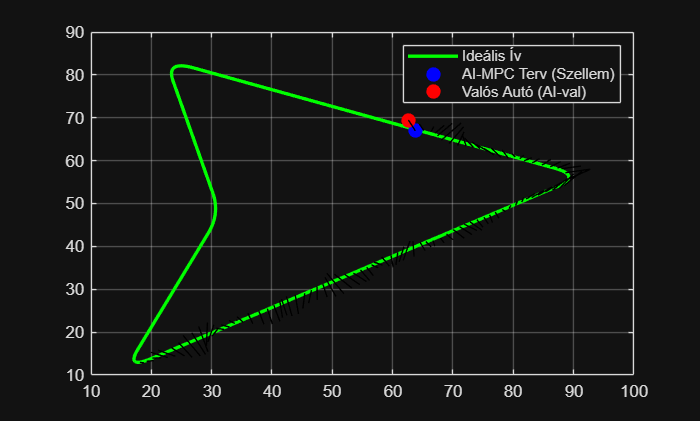

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  75.00us (  6.25us)        12
       nlp_g  |        0 (       0) 134.00us ( 11.17us)        12
  nlp_grad_f  |        0 (       0) 119.00us (  9.15us)        13
  nlp_hess_l  |        0 (       0)  49.00us (  4.45us)        11
   nlp_jac_g  |        0 (       0) 124.00us (  9.54us)        13
       total  |   1.35 s (  1.35 s)   1.35 s (  1.35 s)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  55.00us (  6.11us)         9
       nlp_g  |        0 (       0)  99.00us ( 11.00us)         9
  nlp_grad_f  |        0 (       0)  82.00us (  8.20us)        10
  nlp_hess_l  |        0 (       0)  37.00us (  4.62us)         8
   nlp_jac_g  |        0 (       0)  96.00us (  9.60us)        10
       total  |  46.00ms ( 46.00ms)  46.63ms ( 46.63ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

Error using casadi.Opti/value (line 954)
Error in Opti::value [OptiNode] at .../casadi/core/optistack.cpp:233:
.../casadi/core/optistack_internal.cpp:1170: Assertion "solved()" failed:
This action is forbidden since you have not solved the Opti stack yet (with calling 'solve').


% 5. VEZÉRLÉSI HUROK
for k = 1 : length(t_sim) - N - 1
    current_ref = RefMatrix(k : k+N, :)';
    
    % --- A) AI BECSLÉS (Inference) ---
    % Előkészítjük a bemenetet az NN-nek (Állapot + Előző gázadás)
    nn_input = dlarray([x_real; u_prev], 'CB'); 
    % Megkérdezzük a hálót, mekkora lesz a maradék hiba (zavarás)
    w_becsult = double(extractdata(predict(net, nn_input)));
    w_becsult = w_becsult(:); % Biztosítjuk, hogy oszlopvektor legyen
    
    % --- B) CasADi MEGOLDÁS ---
    opti.set_value(x0_param, z_nom);       
    opti.set_value(ref_param, current_ref);
    opti.set_value(w_nn_param, w_becsult); % Beadjuk az AI jóslatát a szabályozónak
    
    try
        sol = opti.solve(); 
        v_k_opt = sol.value(U(:, 1)); 
    catch
        v_k_opt = opti.debug.value(U(:, 1)); 
    end
    
    % --- C) BEAVATKOZÁS ÉS DINAMIKA ---
    % Tube MPC javítás (LQR)
    u_k = v_k_opt - K_lqr * (x_real - z_nom);
    u_k = max(min(u_k, 25), -25);
    u_prev = u_k; 
    
    % Nominális modell frissítése (ő is tudja az AI jóslatot)
    z_nom = A * z_nom + B * v_k_opt + w_becsult; 
    
    % VALÓSÁG (Légellenállás + kis zaj)
    drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts; 
    drag_y = -0.02 * x_real(4) * abs(x_real(4)) * Ts;
    w_valos = [0; 0; drag_x; drag_y] + [0; 0; randn()*0.05; randn()*0.05];
    
    % Az autó tényleges elmozdulása
    x_real = A * x_real + B * u_k + w_valos;
    
    % --- D) STATISZTIKA ÉS PLOT ---
    real_history = [real_history; x_real'];
    % Számoljuk a letérést a zöld vonaltól
    hibak_tomb = [hibak_tomb; norm(x_real(1:2) - current_ref(1:2, 1))];
    
    if mod(k, 3) == 0 
        set(h_nom, 'XData', z_nom(1), 'YData', z_nom(2));
        set(h_real, 'XData', x_real(1), 'YData', x_real(2));
        % Rajzoljuk a "csövet" (Tube)
        plot([z_nom(1), x_real(1)], [z_nom(2), x_real(2)], '-k', 'LineWidth', 0.5, 'HandleVisibility', 'off'); 
        drawnow;
    end
end


% Végeredmény kirajzolása
plot(real_history(:,1), real_history(:,2), 'r--', 'LineWidth', 1.5, 'HandleVisibility', 'off');
atlagos_hiba = mean(hibak_tomb);
fprintf('Szimuláció kész! Átlagos letérés az ívről: %.4f méter.\n', atlagos_hiba);